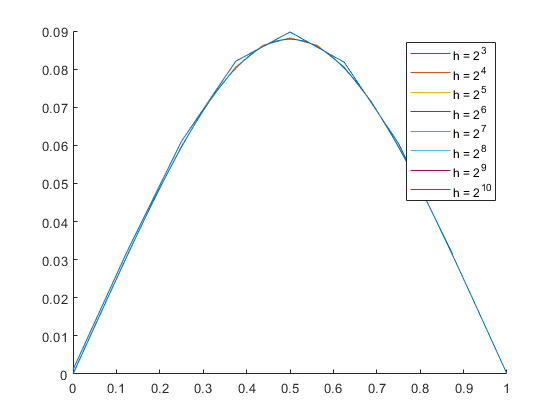

clear all;
L0 = 3;
L1 = 10;
LegendNames = [];
figure()
hold on
for L=L0:L1
    h = 2^-L; %step size
    N = 1/h;
    A_temp = zeros(N); %empty Ah matrix
    A_temp(1,1) = -3;
    A_temp(1,2) = 2;
    A_temp(1,3) = -1;
    for i = 2 : N
        if (i+1) <= N
            A_temp(i,i+1) = -1;
        end
        if (i-1) > 0
            A_temp(i,i-1) = -1;
        end
        A_temp(i,i) = 2;
    end
    
    A = A_temp / h^2;% resulting A matrix
  
    x = h*(0:N-1);
    f = (1-cos(2*pi*x))/2;
   
    Lu = -2*pi^2*cos(2*pi*x);
    %Lu(1) = 0;
    %Lu(N) = 0;
    
    r = f*A - Lu;
    
    U =  A\transpose(f);
    plot(x,U)
    LegendNames = [LegendNames; "h = 2^{" + string(L) + "}"];
    
    rL = r(2:N);
    rB = [r(2); r(N-1)];
    rhoL(L-L0+1) = norm(rL)/sqrt(length(rL));
    rhoB(L-L0+1) = norm(rB)/sqrt(length(rB));
end
legend(LegendNames) 


rhoL

rhoL =     0.6508    0.1724    0.0441    0.0111    0.0028    0.0007    0.0002    0.0000


rhoB

rhoB =     0.4970    0.2076    0.0603    0.0157    0.0040    0.0010    0.0002    0.0001



for i = 2:length(rhoL)
    fL(i) = rhoL(i-1)/rhoL(i);
    fB(i) = rhoB(i-1)/rhoB(i);
end

fL

fL =          0    3.7747    3.9131    3.9627    3.9829    3.9918    3.9960    3.9980


fB

fB =          0    2.3940    3.4405    3.8536    3.9630    3.9907    3.9977    3.9994



ans =

  1024×0 empty double matrix

